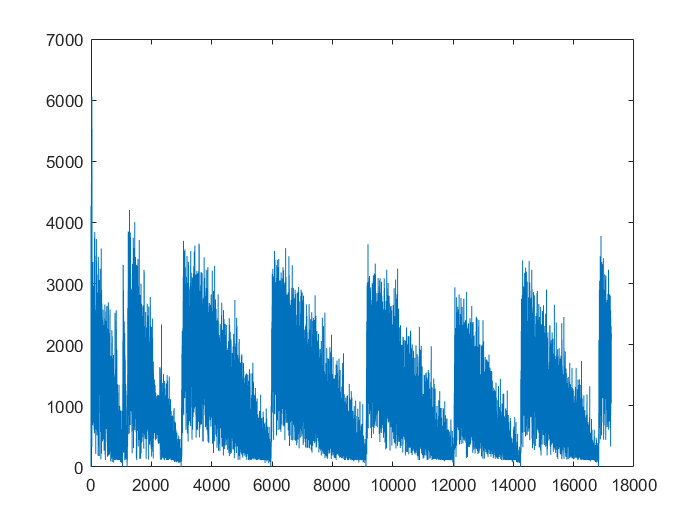

figure(1)
plot(tank_volume_list)

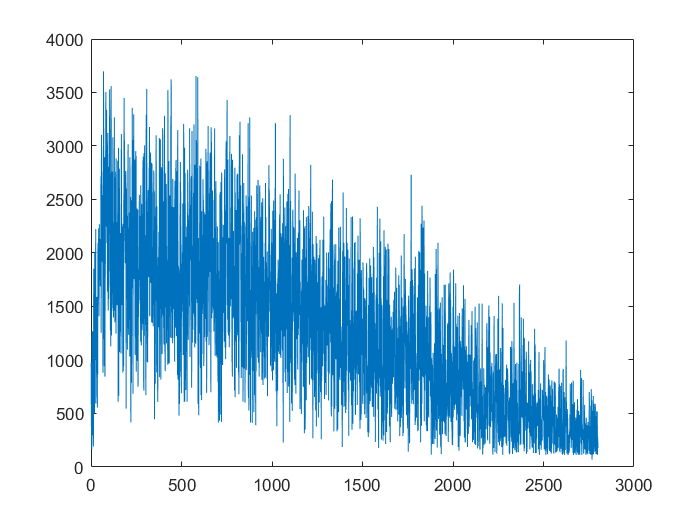


figure(2)
seg = tank_volume_list(3000:5800);
plot(seg)

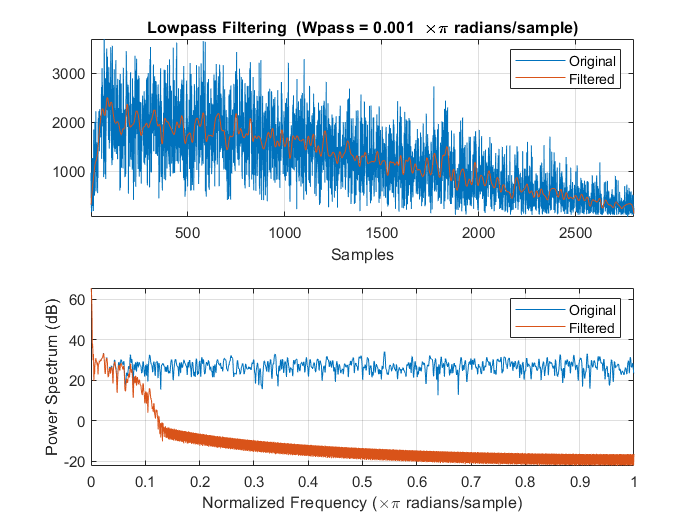


figure(3)
wpass = 0.001;
lowpass(seg,wpass)

Method 1

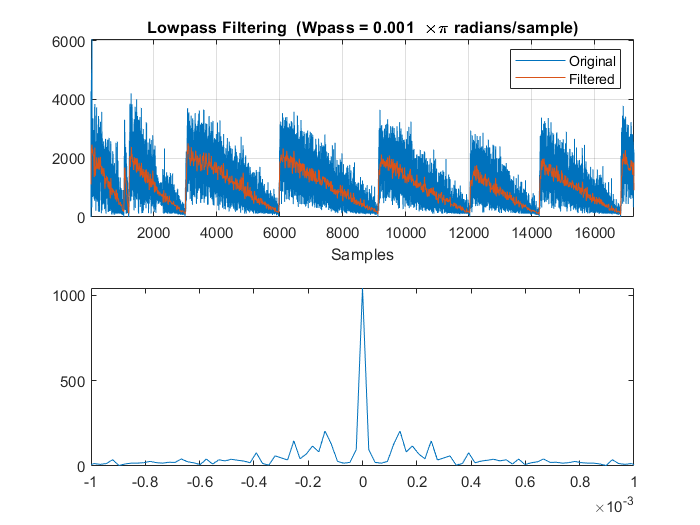

% lowpass function
figure(4)
lowpass(tank_volume_list,wpass)

x = tank_volume_list;
Fs = length(x)/time_list(end);

if(mod(length(x),2) ~=0)
    x = x(1:end-1);
end

% frequency domain
freq_domain = linspace(-Fs/2, Fs/2-Fs/length(x),length(x));

% plot fft of signal over frequency domain
fft_x = fftshift(abs(fft(x)));
plot(freq_domain, 1/length(x)* fft_x);
xlim([-0.001 0.001])


% find top 5 maximum amplitude value and corresponding index
[max_amp, max_i] = maxk(1/length(x)*fft_x,7);

% find maximum frequency 
max_freq = freq_domain(max_i);% Hz

% take only the positive max frequency
max_freq = max_freq(max_freq > 0) % Hz

max_freq = 	1.0e+-3 *

    0.1380    0.2531    0.1150



% convert freq to period
batch_hour = (1./max_freq)/(60*60) % hour

batch_hour =     2.0124    1.0977    2.4149


Method 2? How to reconstruct meaingful data

% use fft and ifft to filter
figure(5)
X = abs(fft(tank_volume_list));
X()

ans = 	1.0e+07 *

    1.7977
    0.1657
    0.0371
    0.0282
    0.0469
    0.2215
    0.3538
    0.1420
    0.2020
    0.1214


X(X~=min(maxk(X,5)))= 0

X = 	1.0e+06 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


Y = ifft(X)

Y =   293.8373
  293.8349
  293.8279
  293.8161
  293.7996
  293.7783
  293.7524
  293.7217
  293.6863
  293.6462


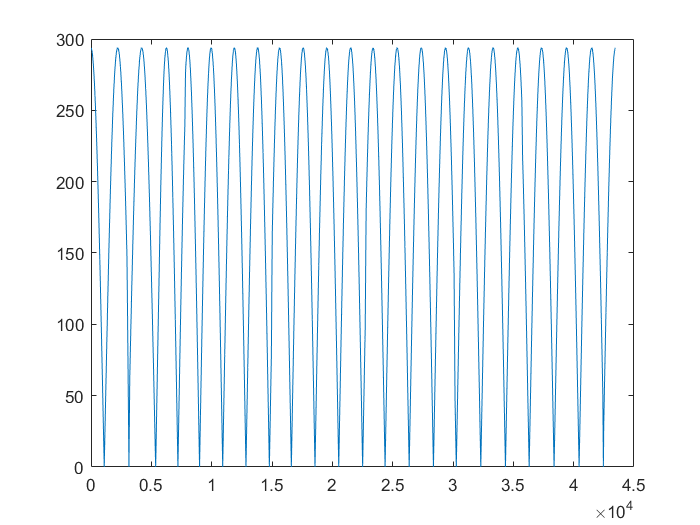

plot(time_list, abs(Y))